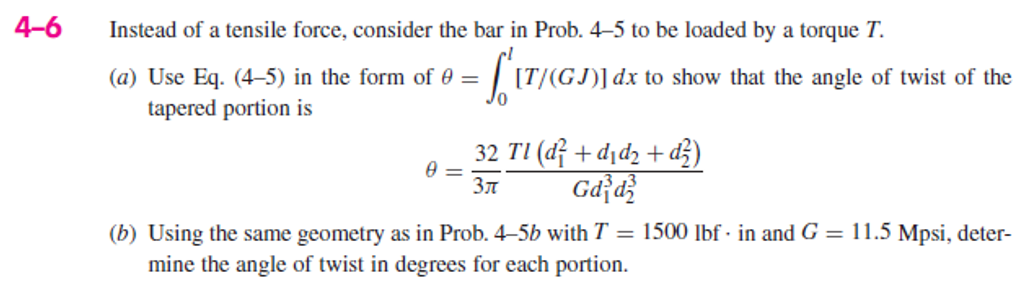

# assumptions

old_assum = assumptions;
clearassum;

# given

u = symunit;
T = sym('T', 'positive');
L = sym('L', 'positive');
D = sym('D', [1 2], 'positive');
G = sym('G', 'positive');
x = sym('x');

# elongation formula

Dfun = findpoly(1, 'thru', [0 D(1)], [L D(2)]);
Jfun = sympi*(Dfun/2)^4/2;
thetafun([T L D G]) = int(T/(Jfun*G), [0 L])

$$thetafun(T, L, D1, D2, G) = \frac{32\,L\,T\,\left({D_{1}}^{2}+D_{1}\,D_{2}+{D_{2}}^{2}\right)}{3\,{D_{1}}^{3}\,{D_{2}}^{3}\,G\,\pi }$$

# elongation of each bar portion

args = {1500*u.lbf*u.in, 2.0*u.in, [0.5; 0.5; 0.75]*u.in, [0.5; 0.75; 0.75]*u.in, 11.5e6*u.psi};
theta = rewrite(simplify(thetafun(args{:}))*u.rad, u.deg);
theta_vpa = vpa(theta, 3) %#ok

$$theta\_vpa = \left(\begin{array}{c} 2.44\,\deg\\ 1.14\,\deg\\ 0.481\,\deg \end{array}\right)$$

clear theta_vpa;
setassum(old_assum, 'clear');